# **                                                                                                                                                                                                                                                                                                                    Modelo 10Khz Conmutable**

clc
clear all

% Parámetros del conversor Buck
P_nom_buck = 18;         % Potencia nominal en vatios (W)
Vg = 12;           % Tensión de entrada en voltios (V)
Vout_buck = 5;          % Tensión de salida en voltios (V)
f_sw = 10e3            % Frecuencia de conmutación en hercios (Hz)

f_sw = 10000

fsim= 10*f_sw

fsim = 100000

% fsim= 500*f_sw;
Tsim=1/fsim

Tsim = 1.0000e-05

Tsw=1/f_sw

Tsw = 1.0000e-04

Tsimulink=12e-3;

TBPRD =200e6/(2*f_sw);

R = Vout_buck^2/P_nom_buck; % Nomila load. CCM
%%%%%%%%%%%%%%%%%%%%%%%
% Ripples Based on nominal parameters
% Delta_IL_buck = 0.4;
Delta_Vout_buck = 0.05*Vout_buck

Delta_Vout_buck = 0.2500


% Cálculo de la corriente de salida del Buck
Iout_buck = P_nom_buck / Vout_buck;
Delta_IL_buck = Iout_buck*0.3

Delta_IL_buck = 1.0800


% Cálculo del ciclo de trabajo (Duty Cycle) del Buck
D_Buck = Vout_buck / Vg;

% Cálculo de la inductancia del Buck
L_buck = (Vg - Vout_buck) / (f_sw * Delta_IL_buck) * D_Buck

L_buck = 2.7006e-04


% Cálculo de la capacitancia del Buck
C_buck = ((1 / f_sw) * (Delta_IL_buck / 2)) / (8 * (Delta_Vout_buck / 2))

C_buck = 5.4000e-05


F_cutLPF = 1/(2*pi*sqrt(L_buck*C_buck));

Scaling_Voltage = (1/Vout_buck)*(2^12)/(3);

% Scaling current to get 1 v at the output.
% Scope Probe scaling must be 5X
Scaling_Current = (1/Iout_buck)*(2^12)/(3);



% PI Controller design

Num=Vg;
Den=[(L_buck*C_buck) L_buck/R 1];

g=tf(Num,Den)


g =
 
                12
  -------------------------------
  1.458e-08 s^2 + 0.0001944 s + 1
 
Continuous-time transfer function.


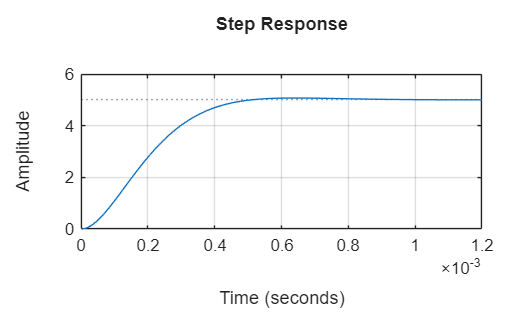

conf_step = RespConfig('InputOffset',0,'StepAmplitude',0.4167);
step(g,conf_step)
grid on


% G=feedback(g,1)
% stepinfo(G)
% bode(G)
% 
% wc=20391;
% T=(2*pi)/wc
% T1=T/8
% T2=T/12
% 
% Ts=Tsw
% 
% Gz=c2d(G,Ts)
% 
% step(G,Gz)
% grid on
% 
% % [num,den]=tfdata(Gz,'v')
%  [z, p, k] = zpkdata(Gz, 'v');
